a = 0.2;
b = 0.5;
j_g = linspace(20,2000,40); %G space
j_d = logspace(0,2,40);

Schnack1m = Sol_Schnack(a,b,j_d,j_g,1e-3);
Schnack1m.j_d = j_d*Schnack1m.d_c;
Schnack1m.predmode = pred_mode(Schnack1m,10)

Schnack1m =   Sol_Schnack with properties:

            a: 0.2000
            b: 0.5000
          j_g: [1×40 double]
          j_d: [1×40 double]
        noise: 1.0000e-03
           u1: [100×40×40 double]
           u2: [100×40×40 double]
      u1_mode: [40×40 double]
      u2_mode: [40×40 double]
     predmode: {[11×599 double]  [10×599 double]  [1×599 double]}
    mode_case: []
    roundProm: [40×40 double]
     rng_seed: [1×1 struct]
         tmax: 1
            A: [2×2 double]
          d_c: 10.1563
          k_g: 40
          k_d: 40
        tspan: [1×100 double]
          mid: [0.7000 1.0204]
          t_k: 100
          x_k: 100
        xspan: [1×100 double]


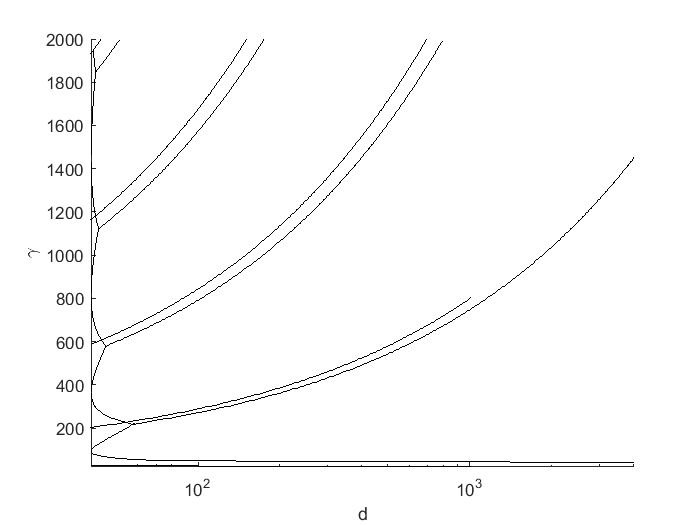

Schnack2m = Schnack1m;
Schnack2m.noise = 1e-4;

Schnack3m = Schnack1m;
Schnack3m.noise = 1e-5;

Schnack_2m = Sol_Schnack(0.3,0.5,j_d,j_g);
Schnack_2m.j_d = j_d*Schnack_2m.d_c;
Schnack_2m.predmode = pred_mode(Schnack_2m,10);


Schnack_23m = Schnack_2m;
Schnack_23m.noise = 1e-5;

Schnack1_median = median_Sol(Schnack1m,5);
Schnack2_median = median_Sol(Schnack2m,5);
Schnack3_median = median_Sol(Schnack3m,10);

Schnack_2median = median_Sol(Schnack_2m,5);
Schnack_23median = median_Sol(Schnack_23m,10);

[Schnack1m,modemode_case1] = median_mode(Schnack1m,Schnack1_median)

ans =     40    40     5


Schnack1m =   Sol_Schnack with properties:

            a: 0.2000
            b: 0.5000
          j_g: [1×40 double]
          j_d: [1×40 double]
        noise: 1.0000e-03
           u1: [100×40×40 double]
           u2: [100×40×40 double]
      u1_mode: [40×40 double]
      u2_mode: [40×40 double]
     predmode: {[11×599 double]  [10×599 double]  [1×599 double]}
    mode_case: [40×40 double]
    roundProm: [40×40 double]
     rng_seed: [1×1 struct]
         tmax: 1
            A: [2×2 double]
          d_c: 10.1563
          k_g: 40
          k_d: 40
        tspan: [1×100 double]
          mid: [0.7000 1.0204]
          t_k: 100
          x_k: 100
        xspan: [1×100 double]


modemode_case1 =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     2     1     1 

[Schnack2m,modemode_case2] = median_mode(Schnack2m,Schnack2_median)

ans =     40    40     5


Schnack2m =   Sol_Schnack with properties:

            a: 0.2000
            b: 0.5000
          j_g: [1×40 double]
          j_d: [1×40 double]
        noise: 1.0000e-04
           u1: [100×40×40 double]
           u2: [100×40×40 double]
      u1_mode: [40×40 double]
      u2_mode: [40×40 double]
     predmode: {[11×599 double]  [10×599 double]  [1×599 double]}
    mode_case: [40×40 double]
    roundProm: [40×40 double]
     rng_seed: [1×1 struct]
         tmax: 1
            A: [2×2 double]
          d_c: 10.1563
          k_g: 40
          k_d: 40
        tspan: [1×100 double]
          mid: [0.7000 1.0204]
          t_k: 100
          x_k: 100
        xspan: [1×100 double]


modemode_case2 =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     2     1     1 

[Schnack3m,modemode_case3] = median_mode(Schnack3m,Schnack3_median)

ans =     40    40    10


Schnack3m =   Sol_Schnack with properties:

            a: 0.2000
            b: 0.5000
          j_g: [1×40 double]
          j_d: [1×40 double]
        noise: 1.0000e-05
           u1: [100×40×40 double]
           u2: [100×40×40 double]
      u1_mode: [40×40 double]
      u2_mode: [40×40 double]
     predmode: {[11×599 double]  [10×599 double]  [1×599 double]}
    mode_case: [40×40 double]
    roundProm: [40×40 double]
     rng_seed: [1×1 struct]
         tmax: 1
            A: [2×2 double]
          d_c: 10.1563
          k_g: 40
          k_d: 40
        tspan: [1×100 double]
          mid: [0.7000 1.0204]
          t_k: 100
          x_k: 100
        xspan: [1×100 double]


modemode_case3 =      2     1     1     2     2     1     1     2     2     2     1     1     2     1     1     1     1     1     1     1     2     2     1     1     2     1     2     1     1     1     1     1     1     2     1     1     2     1     1     1
     2     2     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     2     1     1     2     1     2     1     1     1     1     1     2     1     2     2     2     2     1     1     1     1     1     1     1     1     2     1     1     1     1     2     1     1     2     1     1     1     1     1     1
     2     1     1     1     1     1     1     1     1     1     1     1     2     1     1     1     1     1     1     1     1     1     1     1     1     2     1     1     1     1     1     1     1     1     1     1     1     2     1     2
     1     1     1 

[Schnack_2m,modemode_case_2] = median_mode(Schnack_2m,Schnack_2median)

ans =     40    40     5


Schnack_2m =   Sol_Schnack with properties:

            a: 0.3000
            b: 0.5000
          j_g: [1×40 double]
          j_d: [1×40 double]
        noise: 1.0000e-03
           u1: [100×40×40 double]
           u2: [100×40×40 double]
      u1_mode: [40×40 double]
      u2_mode: [40×40 double]
     predmode: {[11×599 double]  [10×599 double]  [1×599 double]}
    mode_case: [40×40 double]
    roundProm: [40×40 double]
     rng_seed: [1×1 struct]
         tmax: 1
            A: [2×2 double]
          d_c: 40.3097
          k_g: 40
          k_d: 40
        tspan: [1×100 double]
          mid: [0.8000 0.7812]
          t_k: 100
          x_k: 100
        xspan: [1×100 double]


modemode_case_2 =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1

[Schnack_23m,modemode_case_23] = median_mode(Schnack_23m,Schnack_23median)

ans =     40    40    10


Schnack_23m =   Sol_Schnack with properties:

            a: 0.3000
            b: 0.5000
          j_g: [1×40 double]
          j_d: [1×40 double]
        noise: 1.0000e-05
           u1: [100×40×40 double]
           u2: [100×40×40 double]
      u1_mode: [40×40 double]
      u2_mode: [40×40 double]
     predmode: {[11×599 double]  [10×599 double]  [1×599 double]}
    mode_case: [40×40 double]
    roundProm: [40×40 double]
     rng_seed: [1×1 struct]
         tmax: 1
            A: [2×2 double]
          d_c: 40.3097
          k_g: 40
          k_d: 40
        tspan: [1×100 double]
          mid: [0.8000 0.7812]
          t_k: 100
          x_k: 100
        xspan: [1×100 double]


modemode_case_23 =      2     1     1     1     1     1     1     1     1     2     1     2     2     2     2     1     1     2     2     2     1     2     2     2     2     2     2     1     2     2     1     2     2     2     2     2     1     1     2     2
     1     1     1     2     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     2     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     2     2     2     2     1     1     1     2     1     1     1     2     1     1     1     1     2     1     1     2     1     1     2     1     2     2     1     1     2     2     1     2     2     1     1     1     1     1     1     1
     2     1     